# QEA3 Project 1

Jiayuan Liu & Brooklyn Wakefield

**MVP setup:**

clear
clf
% CONSTANTS
h_window_out = 1.4; %W/m^2-K heat transfer coefficient of window
insul_condu = 0.04; %W/m-K fibergalss insulation conductivity
strg_dens = 3000; %kg/m3 storage unit density
strg_spcheat = 800; %J/kg-K storage unit sepecific heat
h_in_surface = 15; %W/m2-K indoor heat transfer coefficient
h_out_surface = 30; %W/m2-K outdoor heat transfer coefficient
T_out_air = -3 + 273.15; %K constant temperature of air outside
A_window = 2.6 * 2.6; %m2 area of window
R_tot_list = [];
strg_thick_list = [];
var_list = [];
label_list = [];

Sweep through multiple insulation thicknesses and record resistances in a list:

for insul_thick = 0.05:0.1:0.05
    for strg_thick = 0.5:0.1:0.5
    % surface areas
    % surface area of insulation layer
    A_insul_in = (3.2 * 5) *2 + (5.1 * 5) * 2 + (3.2 * 5.1) * 2 - A_window; 
    A_insul_out = (3.2 + 2*insul_thick)*(5.1+2*insul_thick)*2 + (3.2+2*insul_thick)*5*2 + (5.1+2*insul_thick)*2*5 - A_window;
    % surface area of heat storage unit (m2)
    A_strg = 2 * 5.1 * 5; 
    
    % volumes
    % volume of heat storage unit (m3)
    V_strg = 5 * 5.1 * strg_thick; 
    % volume of insulation layer (m3)
    V_i_right = 5 * (0.4 + 0.2) * insul_thick;
    V_i_left = (3.2 + 2*insul_thick) * 5 * insul_thick;
    V_i_front_back = 2 * (5.1 + 2*insul_thick) * (3.2 + 2*insul_thick);
    V_i_top_down = (5.1 + 2*insul_thick) * 5 * 2;
    V_insul =  V_i_right + V_i_top_down + V_i_front_back + V_i_left;
    
    % mass of heat storage unit (kg)
    m_strg = V_strg * strg_dens;
    
    % resistances
    % resistance of pathway one: through insulation layer
    
    % heat resistance from tile to inside air (convection)
    R_air_in_t = 1 / (A_strg * h_in_surface); 
    % heat resistance from inside air to insulation (convection)
    R_air_in_i = 1 / (A_insul_in * h_in_surface);
    % heat resistance of insulation layer (conduction)
    R_insul = insul_thick / (A_insul_in * insul_condu);
    % heat resistance from insulation to outside air (convection)
    R_air_out_i = 1 / (A_insul_out * h_out_surface);
    % total resistance for path one
    R_tot_1 = R_air_in_t  + R_air_in_i + R_insul + R_air_out_i;
    
    % resistance of pathway two: through window
    % heat resistance of inside air to window (convection)
    R_air_in_w = 1 / (A_window * h_in_surface);
    % heat resistance of window to outside air (convection)
    R_air_out_w = 1 / (A_window * h_out_surface);
    % heat resistance of window (conduction)
    R_window = 1 / (h_window_out * A_window);
    % total resistance for path two
    R_tot_2 = R_air_in_t  + R_air_in_w + R_window + R_air_out_w;

    
    % thickness of storage unit
    % strg_thick_list(end+1,1) = strg_thick;
    % total resistance: path one and two in parallel
    R_tot =  1 / (1/ R_tot_1 + 1/ R_tot_2);
    R_tot_list(end+1,1) = R_tot;
    
    % list of total resistance and storage unit thickness
    var_list(end+1,:) = [strg_thick,R_tot,insul_thick];
    end
end



**OED equations: **

m*c* **dTs/dt** = Q_sun - Q_window - Q_insul 

tspan = [0 24*300*3600];
T0 = 273.15 + 0;
[row,col] = size(var_list)

row = 1

col = 3


for i = 1:row
    vars = var_list(i,:);
    % T: temperature of the heat storage unit
    [t,T] = ode45(@(t, T) odefun(t, T, vars), tspan, T0);
    % Tair = temperature of the inside air
    T_air = T - (R_air_in_t / R_tot_list(i)) * (T - T_out_air);
    plot((t(600:603)-t(600))/3600, T_air(600:603)-273.15)
    %plot(t/3600, T_air-273.15)
    label_list(end+1,:) = [var_list(i,1),var_list(i,3)];
    T_air-273.15
    hold on
end

ans =    -0.3185
   -0.8818
   -0.7422
    0.9879
    2.2314
    2.0603
    2.2761
    2.9253
    4.3925
    5.0439


label_str_list = "storage-insulation thickness(m):  " + string(label_list(:,1)) + "-" + string(label_list(:,2));
legend_list = "storage thickness"

legend_list = "storage thickness"

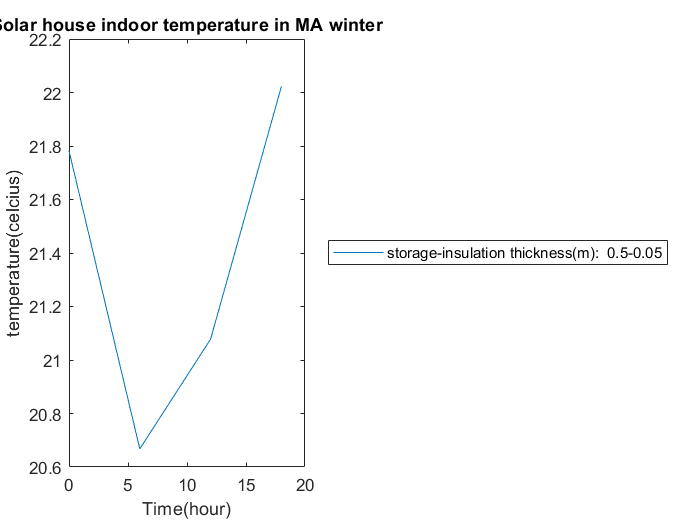

title("Solar house indoor temperature in MA winter")
xlabel("Time(hour)")
ylabel("temperature(celcius)")
legend(label_str_list,"location","eastoutside")

%legend("indoor temperature","location","best")

Handle function:

function dTdt = odefun(t,T,vars)
strg_thick = vars(1);
R_tot_var = vars(2);

T_out_air = -3 + 273.15; %K constant temperature of air outside

% density of storage unit
strg_dens = 3000; %kg/m3 storage unit density

% heat from sun
A_window = 2.6 * 2.6; %m2 area of window
q_sun_at25d = -361*cos(pi*t/(12*3600)) + 224*cos(pi*t/(6*3600)) + 210; %W/m2,t in sec
Q_sun = A_window * q_sun_at25d; %W  total heat flow in from window

c = 800; %J/kg-K storage unit sepecific heat

V_strg = 5 * 5.1 * strg_thick; 
m = strg_dens * V_strg; %kg storage unit mass

dTdt = Q_sun / (m * c) - ((T - T_out_air)/R_tot_var)/(m * c);

end